# **Md Toufique Hasan**

# **Student Number: 151129267**

# **Machine Learning Algorithms: Exercise 5 **

# **Date: 20.04.2023**

## ***Answer: 1***

% Define the observation table
data = {'Outlook', 'Temperature', 'Humidity', 'Windy', 'Class';
        'Sunny', 'Hot', 'High', 'False', 'N';
        'Sunny', 'Hot', 'High', 'True', 'N';
        'Overcast', 'Hot', 'High', 'False', 'P';
        'Rain', 'Mild', 'High', 'False', 'P';
        'Rain', 'Cool', 'Normal', 'False', 'P';
        'Rain', 'Cool', 'Normal', 'True', 'N';
        'Overcast', 'Cool', 'Normal', 'True', 'P';
        'Sunny', 'Mild', 'High', 'False', 'N';
        'Sunny', 'Cool', 'Normal', 'False', 'P';
        'Rain', 'Mild', 'Normal', 'False', 'P';
        'Sunny', 'Mild', 'Normal', 'True', 'P';
        'Overcast', 'Mild', 'High', 'True', 'P';
        'Overcast', 'Hot', 'Normal', 'False', 'P';
        'Rain', 'Mild', 'High', 'True', 'N'};

% Convert the categorical variables to numerical labels
for i = 1:size(data, 2)-1
    [unique_labels, ~, labels(:, i)] = unique(data(2:end, i));
    data(2:end, i) = num2cell(labels(:, i));
end

% Create a decision tree using information gain
tree = fitctree(cell2mat(data(2:end, 1:end-1)), data(2:end, end), ...
    'SplitCriterion', 'deviance');

% View the decision tree
view(tree);

Decision tree for classification
1  if x1<1.5 then node 2 elseif x1>=1.5 then node 3 else P
2  class = P
3  if x3<1.5 then node 4 elseif x3>=1.5 then node 5 else P
4  class = N
5  class = P



## ***Answer: 2***

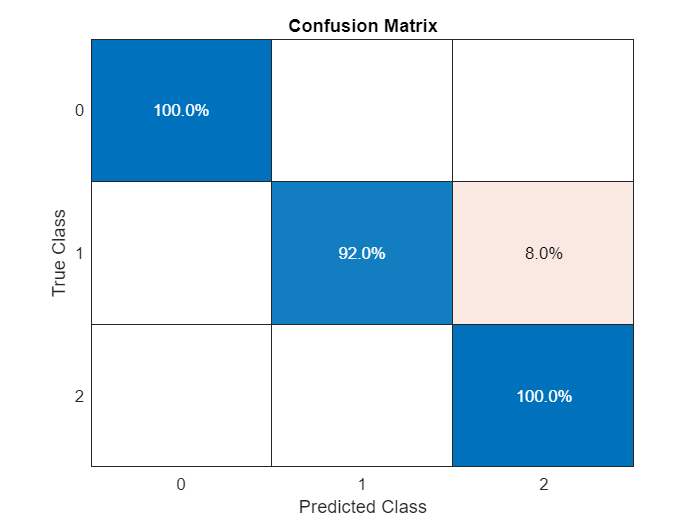

% Load the Iris dataset
load fisheriris

% Extract the feature matrix X and the class labels y
X = meas;
y = categorical(species); % Convert the species names 

% Convert the categorical array 
y = double(y) - 1;

% Split the data into training and test sets
train_indices = [];
test_indices = [];
for i = 0:2
    indices = find(y == i);
    train_indices = [train_indices; indices(1:25)];
    test_indices = [test_indices; indices(26:end)];
end
X_train = X(train_indices, :);
y_train = y(train_indices);
X_test = X(test_indices, :);
y_test = y(test_indices);

% Build a decision tree using the training data
tree = fitctree(X_train, y_train);

% Test the performance of the tree using the test set
y_pred = predict(tree, X_test);

% Create a confusion matrix
C = confusionmat(y_test, y_pred);

% Plot the confusion matrix
figure
confusionchart(C, {'0', '1', '2'}, ...

    'Normalization', 'row-normalized', 'Title', 'Confusion Matrix');

## ***Answer: 3***

% Required Data Has Been Loaded

## ***Answer: 4***

% Tools Has Been Downloaded

## ***Answer: 5***

% Determine the training size as 80% of the total data
trainSize = round(0.8 * size(imageData, 1));

% Randomly sample training data and labels without replacement
idx = randperm(size(imageData, 1));
trainData = imageData(idx(1:trainSize), :);
trainLabels = imageLabels(idx(1:trainSize));

% Use the remaining data as test data and labels
testData = imageData(idx(trainSize+1:end), :);
testLabels = imageLabels(idx(trainSize+1:end));

% Train a decision tree model using the training data and labels
treeModel = fitctree(trainData, trainLabels);

% Predict the labels of the test data using the trained model
predictedLabels = predict(treeModel, testData);

% Calculate the accuracy of the model
modelAccuracy = sum(predictedLabels == testLabels) / numel(testLabels);

## ***Answer: 6***

% Load the reduced Caltech101 map data
load('Caltech101_reduced_map');

% Combine the data and labels into a single matrix
X = [airplanes; cars; faces; keyboard; motorbikes; watch];
Y = [ones(size(airplanes, 1), 1); 2*ones(size(cars, 1), 1); 
    3*ones(size(faces, 1), 1); 4*ones(size(keyboard, 1), 1); 
    5*ones(size(motorbikes, 1), 1); 6*ones(size(watch, 1), 1)];
T = [X, Y];

% Split the data into training
cv = cvpartition(size(T, 1), 'HoldOut', 0.2);
trainIdx = training(cv);
testIdx = test(cv);
trainData = T(trainIdx, :);
testData = T(testIdx, :);

% Train a decision tree model
svmModel = fitctree(trainData(:, 1:end-1), trainData(:, end));

% Predict the labels of the test data
predictedLabels = predict(svmModel, testData(:, 1:end-1));

% Calculate the confusion matrix
confMatrix = confusionmat(testData(:, end), predictedLabels);
disp(confMatrix);